# FSK Modulation

% Parameters
symbol_rate = 1e6; % 1 MHz symbol rate Fs
Fs = symbol_rate

Fs = 1000000

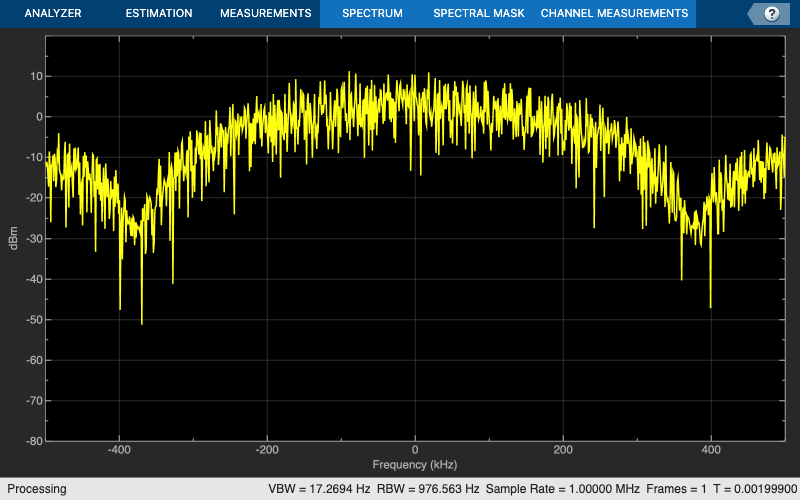

freq_sep = symbol_rate / 4  ; % Frequency separation (for binary FSK)
data_length = 1000;
data = randi([0, 1], 1, data_length); % Example: Generate random binary data

% Modulation
modulation_order = 2; % Binary FSK
nsamp = 2; % Number of samples per symbol (adjusted to an integer greater than 1)

% Modulation using variables
carrier_frequency = symbol_rate / 2; % Corrected carrier frequency calculation
modulated_signal = fskmod(data, modulation_order, freq_sep, nsamp, symbol_rate);
data_demod = fskdemod(modulated_signal, modulation_order, freq_sep, nsamp, symbol_rate);

%constDiagram = comm.ConstellationDiagram;
%constDiagram(modulated_signal.');



modulated_signal = modulated_signal.';
% modulated_signal = lowpass(modulated_signal, 3e5, symbol_rate);
specAnal = spectrumAnalyzer(SampleRate=Fs);
specAnal(modulated_signal)

modulated_signal = modulated_signal.';

## Plot the modulated signal

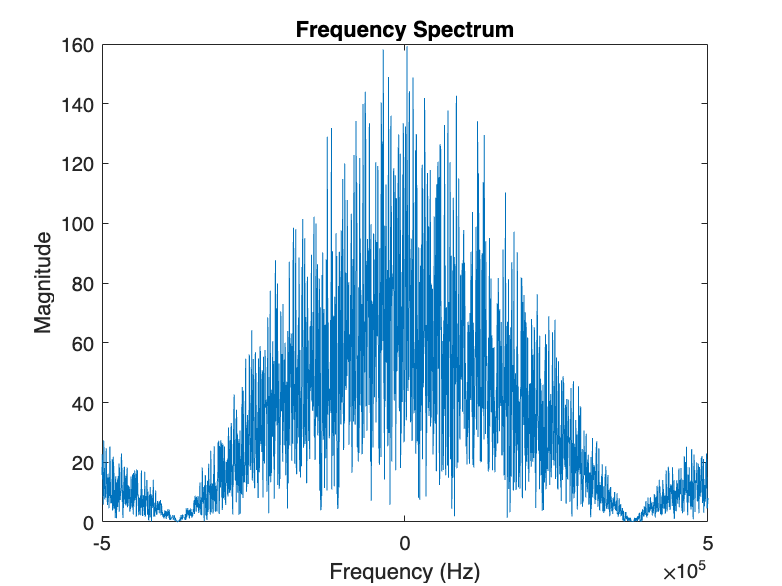

data_demod_t = fskdemod(modulated_signal, modulation_order, freq_sep, nsamp, symbol_rate);

Fs = symbol_rate;
smallw = modulated_signal(:,1:length(modulated_signal)/10);
t = (0:length(smallw)-1) / Fs;

% Compute and plot the frequency-domain spectrum
spectrum = fftshift(fft(modulated_signal));
frequencies = linspace(-Fs/2, Fs/2, length(spectrum));
figure;
plot(frequencies, abs(spectrum));
title('Frequency Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude');



time_axis = (0:(data_length * nsamp) - 1) / (symbol_rate);
figure;
plot(t, smallw);

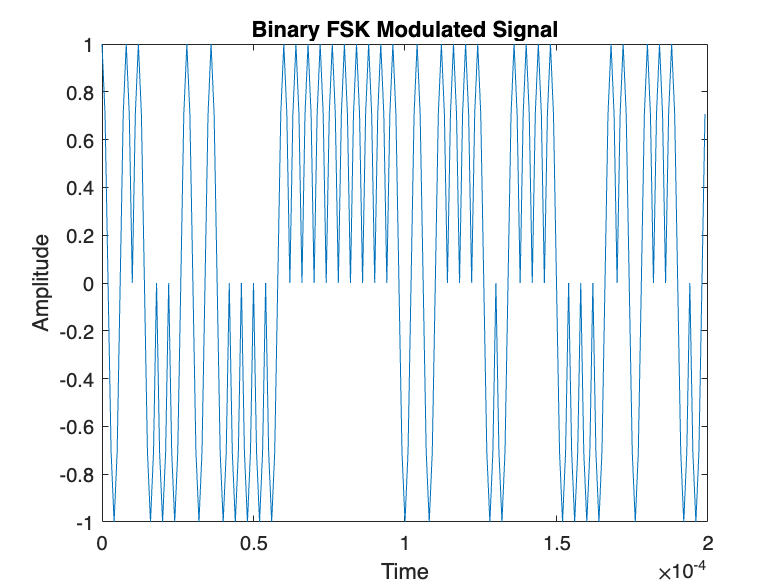

title('Binary FSK Modulated Signal');
xlabel('Time');
ylabel('Amplitude');


t = (0:length(smallw)-1) / Fs;
instantaneous_phase = unwrap(angle(hilbert(smallw)));

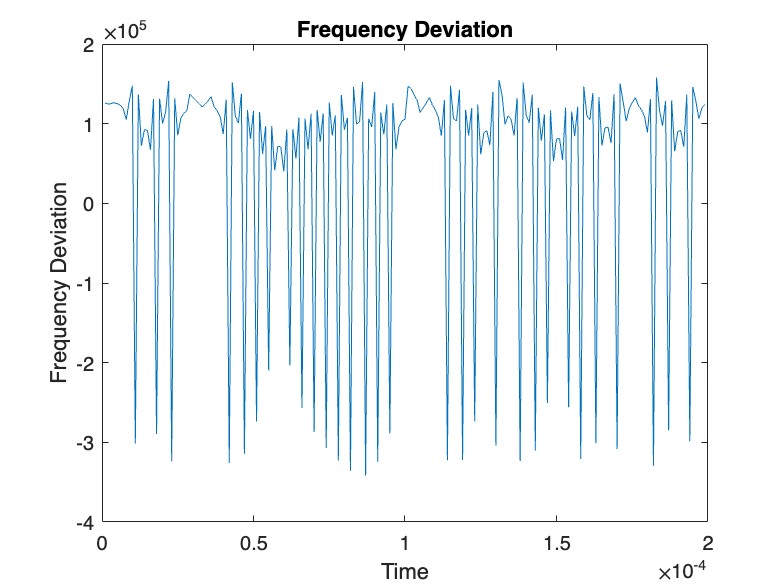


% Compute the frequency deviation
frequency_deviation = diff(instantaneous_phase) / (2 * pi * (t(2) - t(1)));


% Plot the frequency deviation
figure;
plot(t(2:end), frequency_deviation);
title('Frequency Deviation');
xlabel('Time');
ylabel('Frequency Deviation');